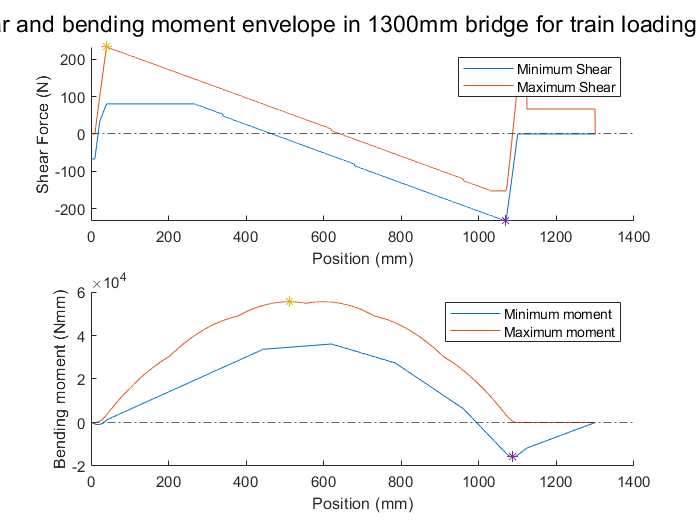

clc
clear
close all

% Notes
% s is a variable representing the position of the leftmost train wheel from the left edge
% of the bridge.
% The train was modelled as 6 point loads at the location of each pairs of
% wheels.
% We loop through all possible positions of the train and calculate SF and
% BM. We then take the max and min and plot them.


bridge_length = 1300;
step=.05;
s_step = 1;


x_range = 0:step:bridge_length;
s_range = 0:s_step:444;

% Matrices where each row is the values of sf/bm for all x given a specific
% s.
sf = zeros(length(s_range), length(x_range));
bm = zeros(length(s_range), length(x_range));

% Calculate for each s value
for s = s_range
    sf(len_to_i(s, s_step), :) = calc_sf(s, step, bridge_length);
    bm(len_to_i(s, s_step), :) = cumtrapz(step, sf(len_to_i(s, s_step), :));
end

% Calculate min and max
min_sf = min(sf);
max_sf = max(sf);
min_bm = min(bm);
max_bm = max(bm);

[bm_max_pks, bm_max_loc] = max(max_bm);
[bm_min_pks, bm_min_loc] = min(min_bm);

[sf_max_pks, sf_max_loc] = max(max_sf);
[sf_min_pks, sf_min_loc] = min(min_sf);

%Plot
sgtitle("Shear and bending moment envelope in 1300mm bridge for train loading case")

subplot(2,1,1)
hold on
plot(x_range, min_sf)
plot(x_range, max_sf)
plot(x_range(sf_max_loc), sf_max_pks, "*")
plot(x_range(sf_min_loc), sf_min_pks, "*")
yline(0, "-.");
ylabel("Shear Force (N)")
xlabel("Position (mm)")
legend("Minimum Shear", "Maximum Shear")
 
subplot(2,1,2)
hold on
plot(x_range, min_bm)
plot(x_range, max_bm)
plot(x_range(bm_max_loc), bm_max_pks, "*")
plot(x_range(bm_min_loc), bm_min_pks, "*")
yline(0, "-.");
ylabel("Bending moment (Nmm)")
xlabel("Position (mm)")
legend("Minimum moment", "Maximum moment")

function sf = calc_sf(s, step, length)
x = 0:step:length;
change = zeros(size(x));

support_a = len_to_i([10, 40], step);
distributed_load = A_y(s) / len_to_i(30, step); % per step

for i = support_a(1):support_a(2)
    change(i) = distributed_load;
end


support_b = len_to_i([1070, 1100], step);
distributed_load = B_y(s) / len_to_i(30, step);

for i = support_b(1):support_b(2)
    change(i) = distributed_load;
end

% The train's six wheels
change(len_to_i(s, step)) = change(len_to_i(s, step)) -400/6;
change(len_to_i(s+176, step)) =change(len_to_i(s+176, step)) -400/6;
change(len_to_i(s+340, step)) =change(len_to_i(s+340, step)) -400/6;
change(len_to_i(s+516, step)) =change(len_to_i(s+516, step)) -400/6;
change(len_to_i(s+680, step)) =change(len_to_i(s+680, step)) -400/6;
change(len_to_i(s+856, step)) =change(len_to_i(s+856, step)) -400/6;

sf = cumsum(change);

end

function result = len_to_i(values, step)
    result = round(values ./ step) +1;
end

function result = B_y(s)
result = 400/1060 * (403+s);
end

function result = A_y(s)
result = 400 - B_y(s);
end